# Parcial 3. Análisis Numérico y Computación Científica

Juan Manuel Ramire

## Primera pregunta

### A. Importacion de datos y proceso inicial

filename='Experimento G1 - 20232.xlsx';
%10100
sheet='CC0';
num = xlsread(filename,sheet);
size(num(:,2))

ans =    120     1


x_null = transpose(num(:,1));
y_null = transpose(num(:,2));

notnull = y_null ~= 0;

x = x_null(notnull)

x =   -10.0000   -9.8319   -9.6639   -9.4958   -9.3277   -8.9916   -8.8235   -8.6555   -8.4874   -8.3193   -8.1513   -7.9832   -7.8151   -7.6471   -7.4790   -7.1429   -6.9748   -6.8067   -6.6387   -6.4706   -6.3025   -6.1345   -5.9664   -5.7983   -5.6303   -5.4622   -5.2941   -5.1261   -4.9580   -4.7899   -4.4538   -4.2857   -4.1176   -3.9496   -3.7815   -3.6134   -3.4454   -3.2773   -3.1092   -2.9412   -2.7731   -2.6050   -2.4370   -2.2689   -2.1008   -1.7647   -1.5966   -1.4286   -1.2605   -1.0924


y = y_null(notnull)

y = 1.0e+04 *

   -3.1215   -2.4331   -2.3529   -2.0251   -2.0976   -1.2650   -1.4974   -1.5511   -1.3330   -1.0725   -0.9758   -0.9940   -0.7074   -0.7655   -0.8627   -0.4856   -0.2152   -0.5238   -0.2988   -0.2208   -0.6652   -0.1247   -0.3679   -0.2156    0.3681    0.2001    0.0751   -0.1072   -0.2338    0.0285   -0.2965   -0.0312   -0.1972    0.2052   -0.1055    0.1233   -0.1131    0.0030    0.0274   -0.0667    0.4275    0.1591    0.2387    0.4192    0.0774   -0.2743   -0.1916   -0.5337   -0.1605   -0.0902


### B. Ajustes

#### i. Exponencial

ly = log(y-min(y)+1)

ly =          0    8.8371    8.9473    9.3025    9.2341    9.8291    9.6954    9.6617    9.7918    9.9278    9.9739    9.9653   10.0917   10.0674   10.0252   10.1796   10.2773   10.1650   10.2481   10.2753   10.1091   10.3079   10.2233   10.2771   10.4602   10.4108   10.3725   10.3138   10.2708   10.3578   10.2489   10.3387   10.2835   10.4124   10.3143   10.3874   10.3118   10.3497   10.3574   10.3271   10.4770   10.3984   10.4224   10.4747   10.3732   10.2567   10.2854   10.1612   10.2959   10.3194


ab1 = regresion(x,ly)

ab1 =    10.2576
    0.0774



$$y = 10.2576e^{0.0774x}+min(y)-1$$


#### ii. Potencial

lx = log(x-min(x)+1)

lx =          0    0.1554    0.2898    0.4083    0.5142    0.6973    0.7777    0.8521    0.9213    0.9861    1.0469    1.1042    1.1584    1.2098    1.2587    1.3499    1.3926    1.4335    1.4728    1.5106    1.5470    1.5822    1.6161    1.6490    1.6808    1.7116    1.7415    1.7705    1.7987    1.8262    1.8789    1.9042    1.9290    1.9531    1.9766    1.9997    2.0222    2.0442    2.0657    2.0868    2.1074    2.1276    2.1475    2.1669    2.1860    2.2230    2.2411    2.2588    2.2762    2.2933


ab2 = regresion(lx,ly)

ab2 =     8.5094
    0.7980



$$y = e^{8.5094}(x-min(x)+1)^{0.798}+min(y)-1$$


#### iii. Razon crecimiento

ix = 1./x

ix =    -0.1000   -0.1017   -0.1035   -0.1053   -0.1072   -0.1112   -0.1133   -0.1155   -0.1178   -0.1202   -0.1227   -0.1253   -0.1280   -0.1308   -0.1337   -0.1400   -0.1434   -0.1469   -0.1506   -0.1545   -0.1587   -0.1630   -0.1676   -0.1725   -0.1776   -0.1831   -0.1889   -0.1951   -0.2017   -0.2088   -0.2245   -0.2333   -0.2429   -0.2532   -0.2644   -0.2767   -0.2902   -0.3051   -0.3216   -0.3400   -0.3606   -0.3839   -0.4103   -0.4407   -0.4760   -0.5667   -0.6263   -0.7000   -0.7933   -0.9154


iy = 1./y

iy =    -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0002   -0.0005   -0.0002   -0.0003   -0.0005   -0.0002   -0.0008   -0.0003   -0.0005    0.0003    0.0005    0.0013   -0.0009   -0.0004    0.0035   -0.0003   -0.0032   -0.0005    0.0005   -0.0009    0.0008   -0.0009    0.0331    0.0037   -0.0015    0.0002    0.0006    0.0004    0.0002    0.0013   -0.0004   -0.0005   -0.0002   -0.0006   -0.0011


ab3 = regresion(ix, iy)

ab3 = 1.0e-03 *

    0.3924
   -0.0766


ab3(1) = 1/ab3(1)

ab3 = 1.0e+03 *

    2.5482
   -0.0000


ab3(2) = ab3(2)/ab3(1)

ab3 = 1.0e+03 *

    2.5482
   -0.0000


ab3(2)

ans = -3.0052e-08


$$y = 2.5482*10^3+\frac{x}{-3.0052*10^{-8}+x}$$


#### iv. Polinomial grado 3

ab4 = regresion([x; x.^2; x.^3], y)

ab4 = 1.0e+03 *

   -1.0510
   -0.9932
    0.0846
    0.0441



$$y = (0.0441x^3+0.0846x^2-0.9932x-1.051)10^3$$


#### v. Polinomial grado 4

ab5 = regresion([x; x.^2; x.^3; x.^4], y)

ab5 =  -151.3813
 -992.9688
   -2.6920
   44.0209
    0.9935


   
$$y = 0.9935x^4 + 44.0209x^3-2.692x^2-992.9688x-151.3813$$


#### vi. Polinomial grado 5

ab6 = regresion([x; x.^2; x.^3; x.^4; x.^5], y)

ab6 =  -119.4536
 -132.4272
   -4.7467
    4.5715
    1.0083
    0.3475



$$y = 0.3475x^5 + 1.00835x^4 + 4.5715x^3-4.7467x^2-132.4272x-119.4536$$


### c. Graficar

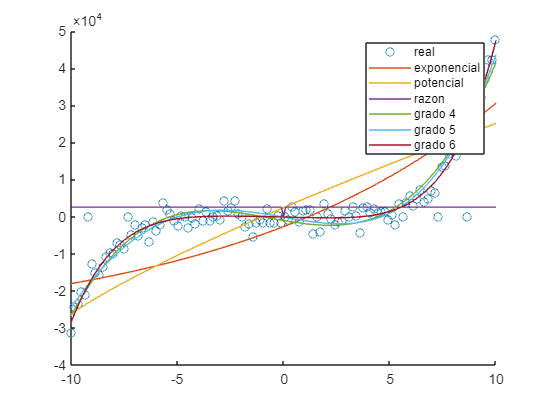

scatter(x_null,y_null)
xlc = x(1):0.1:x(end);
hold on
plot(xlc,exp(ab1(1))*exp(xlc*ab1(2))+min(y)-1)
plot(xlc,exp(ab2(1))*(xlc-min(x)+1).^ab2(2)+min(y)-1)
plot(xlc, ab3(1).*xlc./(ab3(2)+xlc))
plot(xlc,polyval(flip(ab4),xlc))
plot(xlc,polyval(flip(ab5),xlc))
plot(xlc,polyval(flip(ab6),xlc))
hold off
legend('real', 'exponencial', 'potencial', 'razon', 'grado 4', 'grado 5', 'grado 6')

### d. Seleccion de mejor ajuste e interpolacion

sum((y-exp(ab1(1))*exp(x*ab1(2))+min(y)-1).^2)

ans = 4.1340e+11

sum((y-exp(ab2(1))*(x-min(x)+1).^ab2(2)+min(y)-1).^2)

ans = 4.3257e+11

sum((y-ab3(1).*x./(ab3(2)+x)).^2)

ans = 1.7641e+10

sum((y-polyval(flip(ab4),x)).^2)

ans = 7.4832e+08

sum((y-polyval(flip(ab5),x)).^2)

ans = 6.7962e+08

sum((y-polyval(flip(ab6),x)).^2)

ans = 4.6446e+08

De lo anterior podemos concluir que un polinomio de grado 2 minimiza los errores cuadrados en la mejor medida. Por lo tanto al ajustar se tiene:

x_inter = x_null(~notnull)

x_inter =    -9.1597   -7.3109   -4.6218   -1.9328    0.0840    1.5966    3.1092    5.6303    7.3109    8.6555


y_inter = polyval(flip(ab6), x_inter)

y_inter = 1.0e+04 *

   -1.8128   -0.5569   -0.0333    0.0090   -0.0131   -0.0314   -0.0244    0.2780    1.0585    2.3886


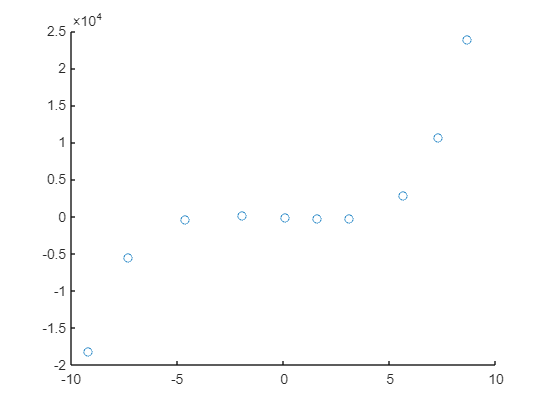

scatter(x_inter, y_inter)

## Segunda pregunta

Del sistema:


$$\frac{\delta^2y}{\delta x^2}+k_1\frac{\delta y}{\delta t} = 0$$


Por metodo de diferencias finitas se obtiene:


$$\frac{1}{\Delta x^2}(Y_{j+1,i}-2Y_{j,i}+Y_{j-1,i}) + \frac{k_1}{\Delta t}(Y_{j,i}-Y_{j,i-|}) = 0$$


Reorganizando:


$$\frac{1}{\Delta x^2}Y_{j+1,i}+(\frac{k_1}{\Delta t}-\frac{2}{\Delta x^2})Y_{j,i}+\frac{1}{\Delta x^2}Y_{j-1,i}  = \frac{k_1}{\Delta t}Y_{j,i-|}$$


Notese que para la primera linea desde la primera iteracion (sin contar t=0):


$$\frac{1}{\Delta x^2}Y_{2,1}+(\frac{k_1}{\Delta t}-\frac{2}{\Delta x^2})Y_{1,1}  = \frac{k_1}{\Delta t}10 - \frac{k_2}{\Delta x^2}$$


Al tener la condicon inicial para el tiempo. Desde la segunda iteracion en adelante 10 se reemplazaria por la temperatura anterior. Por otro lado para la ultima linea se tendra:


$$(\frac{k_1}{\Delta t}-\frac{2}{\Delta x^2})Y_{5,i}+\frac{2}{\Delta x^2}Y_{j4,i}  = \frac{k_1}{\Delta t}Y_{5,i-|}$$


Dado que la condicion de la derivada en L permite asumir la funcion parabolica y por tanto y en x=6 seria igual a y en x = 4. De modo que se llega a la siguiente solucion:

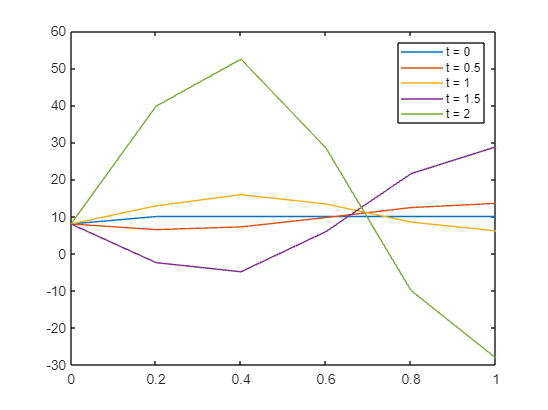

%d2y/dx2 + k1 * d2y/dt
%101008
k1 = 0 + 8;
k2 = 08;
L = 1;
tf = 2;

Tt0 = 10;
dTxL = 0; % Se asume 0, parabola
Tx0 = k2;

dx = 0.2;
dt = 0.5;

nt = tf/dt+1;
nx = L/dx+1;



for i = 1:nt
    if i == 1
        a = diag(ones(1,nx-1));
    else
        a = zeros(nx-1,nx+1);
        a(1,2) = -2/dx^2 + k1/dt;
        a(1,3) = 1/dx^2;
        for j = 2:nx-1
            a(j,j) = 1/dx^2;
            a(j,j+1) = -2/dx^2 + k1/dt;
            a(j,j+2) = 1/dx^2;
        end
        a(nx-1, nx-1) = 2*a(nx-1, nx-1);
        a(nx-1, end) = 0;
        a = a(:,2:nx);
    end
    
    if i == 1
        b = ones(nx-1,1)*Tt0;
    else
        b = y(2:end)*k1/dt;
        b(1) = -Tx0/dx^2+Tt0*k1/dt;
    end
    y = pivoteo(a,b,'parcial',0,false);
    y = [Tx0; y];
    plot(0:dx:L, y,'DisplayName',['t = ',num2str((i-1)*dt)])
    hold on
end
hold off
legend show

%ylim([-6 11])


